% Modified Logistic Growth
% UCI COSMOS 2022:  Tissue and Tumor Modeling (Cluster 3)

clear

## User-defined inputs

TimeStep = 1;           % Time step (baseline = 0.001)
InitialPopulation = 10;    % Initial condition (baseline = 200)
lambdam = .05;                % Growth rate (baseline = 1)
theta = 1000;               % Carrying capacity (baseline = 1000)
alpha = .43;                  % Exponent (baseline = 2)
endTime = 150;               % End time of simulation (baseline = 10)

% Note: If alpha is 1, this becomes the orginal Logistic Growth model.

## Begin simulation

% Program execution parameters
dT = TimeStep;
tsteps = ceil(endTime/dT) + 1;    % Number of time steps required

% Pre-allocate vectors for faster runtime
Time = zeros(1,tsteps);
N = zeros(1,tsteps);

% Set initial time and initial population
Time(1) = 0;                % Set initial time to zero
N(1) = InitialPopulation;   % Set initial population

% Euler Method
for n = 2:tsteps
    Time(n) = (n-1)*dT;
    N(n) = N(n-1) + dT*( lambdam*N(n-1)*(1-(N(n-1)/theta)^alpha) );
end

## Simplified Modified Logistic Growth

raw = readtable("Raw data_MCSBBootcampBacterialPopulationGrowth.txt");

data = table2array(raw);


noglu = data(:,2);
noglu2 = zeros(1,length(noglu));
for i = 1:length(noglu)
    noglu2(1,i) = noglu(i)*1000;
end
noglu2

noglu2 =     35    74    99   208   407   531


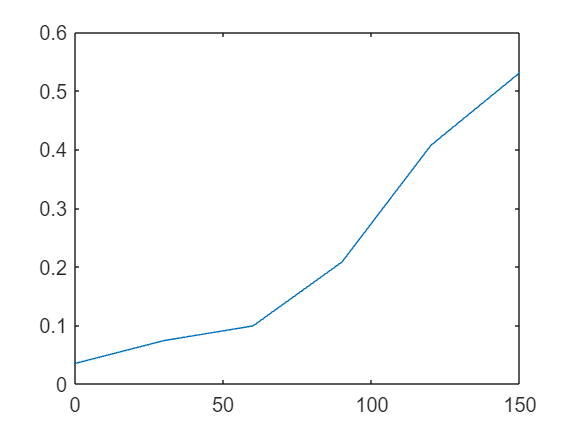

time = data(:,1);
plot(time,noglu)


arrayg = 1:30:151;
diffval = zeros(2,length(arrayg));
for i = 1:length(arrayg)
    diffval(1,i) = ExactPopulation(arrayg(i));
    diffval(2,i) = noglu2(i);
end

diffs = zeros(1,length(diffval));
for i = 1:length(diffval)
    diffs(1,i) = (diffval(1,i) - diffval(2,i))^2;
end
sse = sum(diffs)

sse = 82.7921

## Plotting

## Exact Solution to the simplified MLG

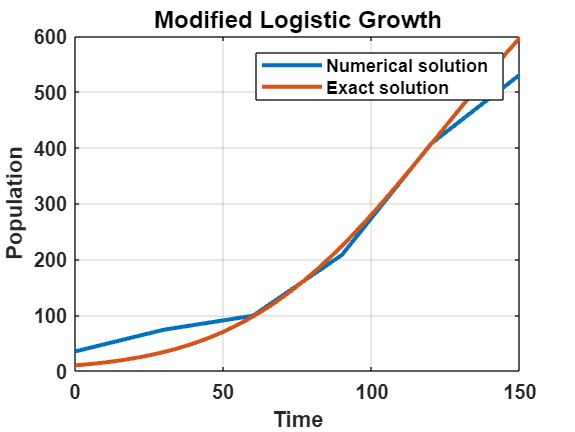

ExactPopulation = theta*((N(1)^alpha)./(N(1)^alpha + (theta^alpha-N(1)^alpha)*exp(-alpha*lambdam*Time))).^(1/alpha);

figure,plot(time,noglu2,Time,ExactPopulation,'LineWidth',2)
xlabel('Time','FontWeight','bold')
ylabel('Population','FontWeight','bold')
grid on
legend('Numerical solution','Exact solution')
title('Modified Logistic Growth','FontSize',12,'FontWeight','bold')
set(gca,'FontWeight','bold')